%-------------------------------------------------------------------------
%   
%          ADJUSTMENT THEORY I
%  Exercise 11: Adjustment Calculation - part VI  
% 
%   Author         : Anastasia Pasioti
%   Version        : October 12, 2018
%   Last changes   : January 25, 2023
%
%-------------------------------------------------------------------------
clc;
 clearvars;
 close all;
 format longG;

%-------------------------------------------------------------------------
%   Task 1
%-------------------------------------------------------------------------
%-------------------------------------------------------------------------
%   Observations and initial values for the unknowns
%-------------------------------------------------------------------------
%Coordinates - error free values
XG = [4316.175 4036.242 2136.262 1324.177]'; %[m]
YG = [935.411 2055.452 2331.535 1189.218]';    %[m]
%Vector of observations
L = [3491.901 2706.417 922.862 1819.298]';   %[m]
%Number of observations
no_n = length(L);
%Initial values for the unknowns
xP = 3000;
yP = 1500;
%Vector of initial values for the unknowns
X_0 = [xP yP]';
%Number of unknowns
no_u = length(X_0);
%Redundancy
r = no_n-no_u;  
%-------------------------------------------------------------------------
%  Stochastic model
%-------------------------------------------------------------------------
%VC Matrix of the observations
s_L = 0.002+2*L*1e-6; %[m]
S_LL = diag(s_L.^2);
%Theoretical standard deviation
sigma_0 = 1;     
%a priori
%Cofactor matrix of the observations
Q_LL = 1/sigma_0^2*S_LL;
%Weight matrix
P = inv(Q_LL);
%-------------------------------------------------------------------------
%  Adjustment
%-------------------------------------------------------------------------
%break-off conditions
epsilon = 1e-5;
delta = 1e-12;
max_x_hat = Inf;
Check2 = Inf;
%Number of iterations
iteration = 0;
while (max_x_hat>epsilon) || (Check2 > delta)           
    %Observations as functions of the approximations for the unknowns
     L_0 = sqrt((XG - xP).^2 + (YG - yP).^2);
    %Vector of reduced observations
     l = L-L_0;
    %Design matrix with the elements from the Jacobian matrix J
     A = [-(XG-xP)./L_0 -(YG-yP)./L_0];
    %Normal matrix
     N = A' * P * A;
    %Vector of right hand side of normal equations
     n = A' * P * l;
     %Inversion of normal matrix / Cofactor matrix of the unknowns
     Q_xx = inv(N);
    
     %Solution of the normal equations
     x_hat = Q_xx * n;
       
     %Update
     X_hat = X_0 + x_hat;
     X_0 = X_hat;
     xP = X_hat(1);
     yP = X_hat(2);
     %Check 1
     max_x_hat = max(abs(x_hat));
     
     %Vector of residuals
     v = A * x_hat - l;
 
     %Vector of adjusted observations
     L_hat = L + v;
    
     %Objective function
     vTPv = v' * P * v;
    
     %Functional relationships without the observations
     phi_X_hat = sqrt((XG - xP).^2 + (YG - yP).^2);
     
     %Check 2
     Check2 = max(abs(L_hat - phi_X_hat));
    
     %Update number of iterations
     iteration = iteration+1;
  
end

if Check2<=delta
disp('Everything is fine!')
else
disp('Something is wrong.')
end

Everything is fine!


%Empirical reference standard deviation
s_0 = sqrt(vTPv/r);
%VC matrix of adjusted unknowns
S_XX_hat = s_0^2 * Q_xx;
%Standard deviation of the adjusted unknowns
s_X = sqrt(diag(S_XX_hat));
%Cofactor matrix of adjusted observations
Q_LL_hat = A * Q_xx * A';
%VC matrix of adjusted observations
S_LL_hat = s_0^2 * Q_LL_hat;
%Standard deviation of the adjusted observations
s_L_hat = sqrt(diag(S_LL_hat));
%Cofactor matrix of the residuals
Q_vv = Q_LL - Q_LL_hat;
%VC matrix of residuals
S_vv = s_0^2 * Q_vv;
%Standard deviation of the residuals
s_v = sqrt(diag(S_vv));
% Results
table(X_hat, s_X, 'RowNames', {'xP' 'yP'})

ans = 2×2 table
               X_hat                  s_X         
          ________________    ____________________

    xP    1500.00019447308    0.000311619838406921
    yP     2999.9999527449    0.000273745240201374


 table(L, v, L_hat, s_v, s_L_hat)

ans = 4×5 table
       L                  v                   L_hat                  s_v                   s_L_hat       
    ________    _____________________    ________________    ____________________    ____________________

    3491.901    -0.000646455977821506    3491.90035354402    0.000461305403749173    0.000188274864100421
    2706.417     6.52611982793232e-05     2706.4170652612    0.000334049723472426    0.000239646831035274
     922.862     0.000112246794631069    922.862112246795    0.000128356169441326    0.000170339883686419
    1819.298     -3.7570168683337e-05    1819.29796242983    0.000108513783114958    0.000293289101181838


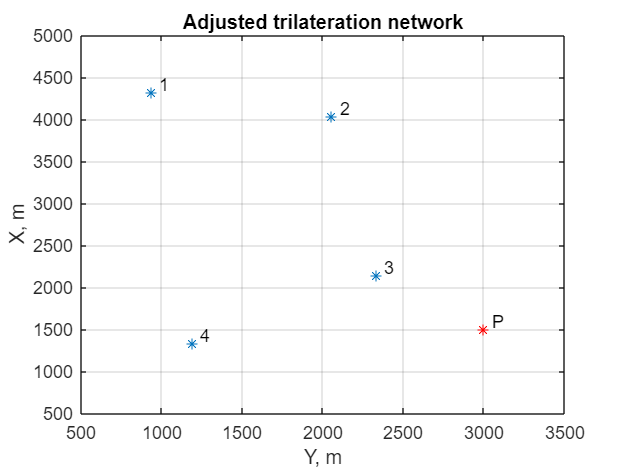

name = (["1" "2" "3" "4"]);
figure
plot(YG, XG,'*')
grid
xlim([500 3500])
ylim([500 5000])
xlabel('Y, m')
ylabel('X, m')
text(YG+50, XG+100, name)
title("Adjusted trilateration network")
hold on
plot(yP, xP, '*', Color='red')
text(yP+50, xP+100, "P")
hold off

 The adjusted position of point P is different from the given on the sketch.